# Decoding results

## Load data

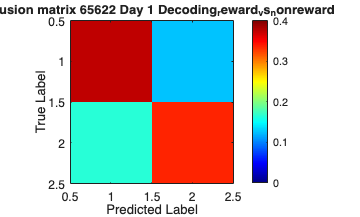

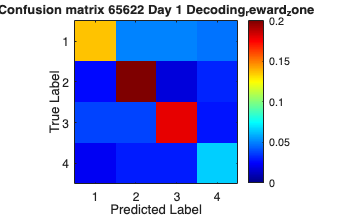

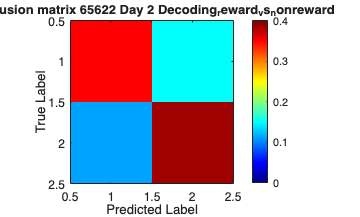

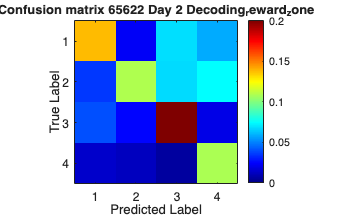

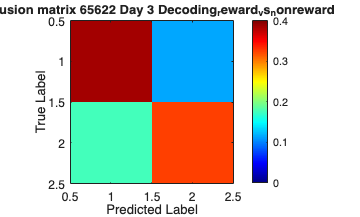

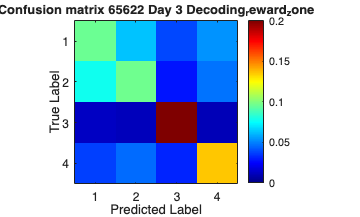

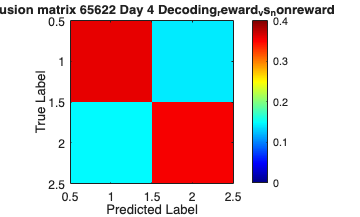

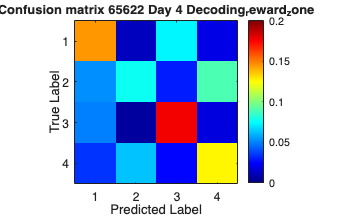

clc; clear; close all;

animalID = [65622,63383,67330,67456,66922,65588,67324,67141];
animals = length(animalID);
bootstraps = 100;
reward_zones = [3,4,7];
control = 1:4;
experimental = 5:8;
colors = {'#284B5E','#BC554C'};                                     % standard group colors 
fold_validation = 5;                                                % number of cross validations
c_colors = linspecer(9);                                            % returns 9 RGB triplets
class_colors = [c_colors(end,:);c_colors(1:8,:)];                   % keep colors consitant across analysis
fixed_classes = 0:8;                                                % all possible class labels
decode_modes = {'Decoding_reward_vs_nonreward','Decoding_reward_zone','Decoding_all_zones'};

main_dir = get_data_root();
meta_table = readtable(fullfile(main_dir,'Metadata.xlsx'),"Sheet",'Data ID');
% load(fullfile(main_dir,'CompiledData/Decoding.mat'));

for a = 1:animals
    identity = [meta_table.animal_id,meta_table.experiment_type];
    date = cell2mat(meta_table.date);

    exp = find((identity(:,1) == animalID(a) & identity(:,2) == 2)+(identity(:,1)== animalID(a) & identity(:,2) == 3));
    [session,~] = size(date(exp,:));
    validity = meta_table.validity(exp);
    d = date(exp,:);

    for s = 1:session
        if validity(s) == 1

        d = date(exp(s),:);
        else

            empty_session = nan(5,1);
            acc{s,1}(:,a) = empty_session;
            acc{s,2}(:,a) = empty_session;
            acc{s,3}(:,a) = empty_session;

            shuffle_acc{s,1}{1,a} ={};
            shuffle_acc{s,2}{1,a} ={};
            shuffle_acc{s,3}{1,a} ={};
        end

        session_num = 'A';
        animal_ID = num2str(animalID(a));

        % load variables
        path = char(fullfile(main_dir,animal_ID,d,session_num,'data/Processed'));
        index = find(strcmp(meta_table.date, d) == 1 & meta_table.animal_id == str2double(animal_ID));
        g = meta_table.genotype(index); % 1 = control, 2 = exp
        day = sprintf('Day %d',s);


        for dm = 1:2
            mode_decoding = decode_modes{dm};
            load(fullfile(path, [mode_decoding '.mat']))
            switch mode_decoding
                case 'Decoding_reward_vs_nonreward'
                    n_classes = 2;
                    mode_classes = [0,1];
                    figure_path = fullfile(main_dir,'Figures/Ingvild/Ephys/Decoding/reward_vs_nonreward');
                case 'Decoding_reward_zone'
                    n_classes = 4;
                    mode_classes = [0,3,4,7];
                    figure_path = fullfile(main_dir,'Figures/Ingvild/Ephys/Decoding/reward_zones');

                case 'Decoding_all_zones'
                    n_classes = 9;
                    mode_classes = [0,1,2,3,4,5,6,7,8];
            end
    
            % retrieve variables
            boot_margins = decoding{7,1};
            boot_true = decoding{3,1};
            boot_accuracy = decoding{1,1};
            boot_shuffle = decoding{2,1};
            
            % Convert cell array into 3D matrix: (1000 x 5 x 100)
            boot_mat = cat(3, boot_shuffle{:});
            
            % Average across the 3rd dimension (bootstraps)
            shuffle = mean(boot_mat, 3);


            % Take mean accuracy across bootstrap iterations:
            % sh = cellfun(@mean, boot_shuffle, 'UniformOutput', false);
            % shuffle = cell2mat(sh);           % [bootstraps × trials]
            shuffle_mean = mean(shuffle,1);
            shuffle_low  = prctile(shuffle,2.5,1);
            shuffle_high = prctile(shuffle,97.5,1);
            
            acc_mean = mean(boot_accuracy,1);
            acc_sd   = std(boot_accuracy,[],1);
            
            figure
            shadedErrorBar(1:numel(acc_mean), acc_mean, acc_sd, ...
                'lineprops', {'Color', colors{g}, 'LineWidth', 3});
            hold on
            fill([1:numel(acc_mean), fliplr(1:numel(acc_mean))], ...
                 [shuffle_low, fliplr(shuffle_high)], ...
                 [0.7 0.7 0.7], 'FaceAlpha',0.3, 'EdgeColor','none');
            plot(1:numel(acc_mean), shuffle_mean, 'Color', [0.4 0.4 0.4], 'LineWidth',2);
            ylim([0,1])
            ylabel('Decoding accuracy')
            xlabel('Trial blocks')
            xticks(1:fold_validation)
            title(sprintf('Accuracy (m ± std) %s %s %s',animal_ID,day,mode_decoding))
            figure_handle = sprintf('Accuracy_%s_%s_%s',animal_ID,day,mode_decoding);
            save_figure(figure_path,figure_handle); 
            close;

            %%%%%%%%%% confusion matrix %%%%%%%%%% 
            if dm ==1
                figure;                             % Create new figure
                ax = axes('Parent', gcf);           % Explicit axes in this figure
                h = imagesc(ax, decoding{6,1});     % Plot numeric matrix
                axis(ax, 'square');                  % Square axes
                colormap(ax, jet);                   % Colormap
                colorbar(ax);                        % Add colorbar
                set(ax, 'CLim', [0 0.4]);            % Set color limits robustly
                
                ylabel(ax, 'True Label');
                xlabel(ax, 'Predicted Label');
                title(ax, sprintf('Confusion matrix %s %s %s', animal_ID, day, mode_decoding));
            else
                figure;                             % Create new figure
                ax = axes('Parent', gcf);           % Explicit axes in this figure
                h = imagesc(ax, decoding{6,1});     % Plot numeric matrix
                axis(ax, 'square');                  % Square axes
                colormap(ax, jet);                   % Colormap
                colorbar(ax);                        % Add colorbar
                set(ax, 'CLim', [0 0.2]);            % Set color limits robustly
                
                ylabel(ax, 'True Label');
                xlabel(ax, 'Predicted Label');
                title(ax, sprintf('Confusion matrix %s %s %s', animal_ID, day, mode_decoding));
            end


            figure_handle = sprintf('ConfusionMatrix_%s_%s_%s',animal_ID,day,mode_decoding);
            print(gcf, '-dsvg', '-painters', fullfile(main_dir,'Figures/Ingvild/Ephys/Paper Prep/decoding/',[figure_handle '.svg']));
            
            
            %%%%%%%%%% SV Margins %%%%%%%%%% 
            fpr_grid = linspace(0,1,100);
            roc_mean = nan(numel(fpr_grid), numel(mode_classes));
            roc_sem  = nan(numel(fpr_grid), numel(mode_classes));
            legend_entries = {};
        
            % get the right colors
            
            color_idx = ismember(fixed_classes,mode_classes)';
            mode_color = class_colors(color_idx,:);
            

            figure
            for ci = 1:numel(mode_classes)
                class_label = mode_classes(ci);
                tpr_all = nan(bootstraps, numel(fpr_grid));

                for b = 1:bootstraps
                    margins_b = boot_margins{b};
                    true_b    = boot_true{b};

                    % Skip if this class never appears in true labels
                    if ~ismember(class_label, true_b)
                        continue
                    end

                    % Grab the margins directly by fixed order
                    scores = margins_b(:,ci);
                    if all(isnan(scores))
                        continue
                    end

                    % Valid indices
                    valid_idx = ~isnan(scores);
                    if sum(true_b(valid_idx) == class_label) < 2
                        continue
                    end

                    % ROC
                    [X,Y] = perfcurve(true_b, scores, class_label);

                    % Interpolation to grid
                    [Xu, ia] = unique(X);
                    Yu = Y(ia);
                    tpr_all(b,:) = interp1(Xu, Yu, fpr_grid, 'linear', 'extrap');
                end

                % Aggregate across bootstraps (same as your code)
                valid_idx = ~all(isnan(tpr_all),2);
                if any(valid_idx)
                    roc_mean(:,ci) = nanmean(tpr_all(valid_idx,:),1);
                    roc_sem(:,ci)  = nanstd(tpr_all(valid_idx,:),[],1) ./ sqrt(sum(valid_idx));

                    shadedErrorBar(fpr_grid(:), roc_mean(:,ci), roc_sem(:,ci), ...
                        'lineprops', {'Color', mode_color(ci,:), 'LineWidth', 2});
                    legend_entries{end+1} = sprintf('Class %d', class_label);
                    hold on
                end
            end
            xlabel('False Positive Rate');
            ylabel('True Positive Rate');
            title(sprintf('ROC Curves (mean ± SEM): %s %s %s', animal_ID, day, mode_decoding));
            legend(legend_entries, 'Location', 'SouthEast');
            grid on;

            figure_handle = sprintf('Margins_%s_%s_%s',animal_ID,day,mode_decoding);
            print(gcf, '-dsvg', '-painters', fullfile(main_dir,'Figures/Ingvild/Ephys/Paper Prep/decoding/',[figure_handle '.svg']));

            close;

            acc{s,dm}(:,a) = acc_mean;  
            shuffle_acc{s,dm}{a} = shuffle;
        end
    end
end

## Plot individual days

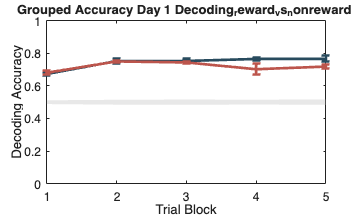

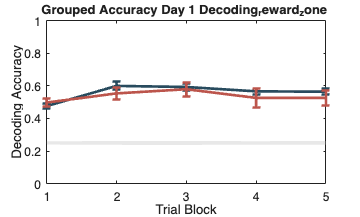

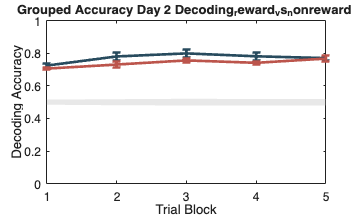

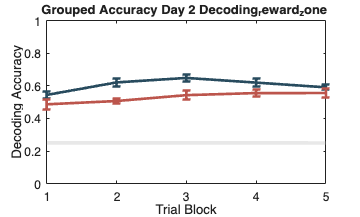

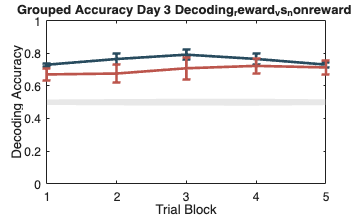

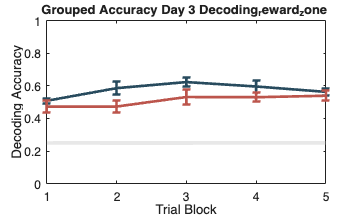

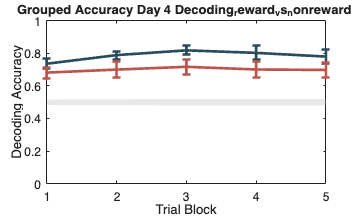

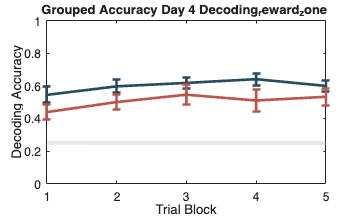

for s = 1:session
    for dm = 1:2%numel(decode_modes)
        contr = acc{s,dm}(:,control);
        exp = acc{s,dm}(:,experimental);
        shuffle = shuffle_acc{s,dm};
        
        % sh = cellfun(@mean, shuffle, 'UniformOutput', false);
        % shuffle_all = cell2mat(sh'); 
        shuffle_all = cell2mat(shuffle'); 
        % shuffle_mean = mean(shuffle,1);
        shuffle_low  = prctile(shuffle_all,5,1);
        shuffle_high = prctile(shuffle_all,95,1);

        % figure('Visible','off')
        figure
        errorbar(mean(contr','omitnan'),SE(contr'),'Color',colors{1},'LineWidth',2)
        hold on
        errorbar(mean(exp','omitnan'),SE(exp'),'Color',colors{2},'LineWidth',2)
        fill([1:5, fliplr(1:5)],[shuffle_low, fliplr(shuffle_high)],[0.7 0.7 0.7], 'FaceAlpha',0.3, 'EdgeColor','none');

        ylim([0,1])
        yticks(0:0.2:1)
        xticks(0:1:5)
        xlabel('Trial Block')
        ylabel('Decoding Accuracy')
        title(sprintf('Grouped Accuracy Day %d %s %s',s,decode_modes{dm}))

        figure_path = fullfile(main_dir,"Figures/Ingvild/Ephys/Decoding",decode_modes{dm},'summary');
        figure_handle = sprintf('Grouped Average Accuracy Day %d %s %s',s,decode_modes{dm});
        save_figure(figure_path,figure_handle); 
        % close;
        
        % Get the average acc for validation
        acc_days{dm,1}(:,s) = mean(contr,'omitnan');
        acc_days{dm,2}(:,s) = mean(exp,'omitnan');
        shuffle_days{dm,1}(:,s) = mean(shuffle_all,2);
        
    end
end

## Plot days

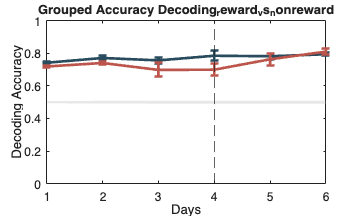

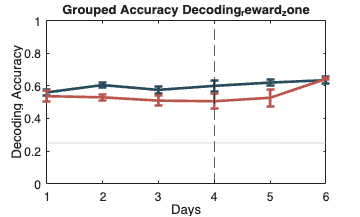

for dm = 1:2 %numel(decode_modes)
    
    contr = acc_days{dm,1};
    exp = acc_days{dm,2};
    shuffle = shuffle_days{dm,1};

    shuffle_low  = prctile(shuffle,5,1);
    shuffle_high = prctile(shuffle,95,1);
        
    figure
    errorbar(mean(contr,'omitnan'),SE(contr),'Color',colors{1},'LineWidth',2)
    hold on
    errorbar(mean(exp,'omitnan'),SE(exp),'Color',colors{2},'LineWidth',2)
    fill([1:6, fliplr(1:6)],[shuffle_low, fliplr(shuffle_high)],[0.7 0.7 0.7], 'FaceAlpha',0.3, 'EdgeColor','none');

    ylim([0,1])
    yticks(0:0.2:1)
    xticks(1:1:6)
    xlabel('Days')
    ylabel('Decoding Accuracy')
    xline(4,'--')
    title(sprintf('Grouped Accuracy %s',decode_modes{dm}))

    % figure_path = fullfile(main_dir,"Figures/Ingvild/Ephys/Decoding",decode_modes{dm},'summary');
    % figure_handle = sprintf('Full Experiment Accuracy %s',decode_modes{dm});
    % save_figure(figure_path,figure_handle); 
    % close;
end

## Stats

% Mixed-effects analysis across replicates, animals, and days 
%   acc{s,m} = [R x N] matrix
%       R = number of replicates per animal (e.g. 5)
%       N = total number of animals
%   session = number of days
%   decode_modes = cell array of decoder type names
%   main_dir = base path for saving

for dm = 1:2%:numel(decode_modes)

    Accuracy = [];
    AnimalID = {};
    Group    = {};
    Day      = [];

    for s = 1:session
        data = acc{s,dm};    % R x N
        [R, N_all] = size(data);

        for a = 1:N_all
            coldata = data(:,a); % R x 1 (may contain NaN)

            thisAnimal = sprintf('A%02d', a);

            if ismember(a, control)
                g = 'Control';
            elseif ismember(a, experimental)
                g = 'Experimental';
            end

            % Append (keep NaNs for now, ensures alignment)
            Accuracy = [Accuracy; coldata(:)];
            AnimalID = [AnimalID; repmat({thisAnimal}, R, 1)];
            Group    = [Group; repmat({g}, R, 1)];
            Day      = [Day; repmat(s, R, 1)];
        end
    end

    % Convert to table
    T = table(Accuracy, categorical(AnimalID), categorical(Group), categorical(Day), ...
              'VariableNames', {'Accuracy','AnimalID','Group','Day'});

    % Drop NaN rows 
    T = T(~isnan(T.Accuracy), :);

    % ---------------------------
    % Fit linear mixed-effects model
    % ---------------------------
    lme = fitlme(T, 'Accuracy ~ Group*Day + (1|AnimalID)', 'FitMethod','REML');

    % Get ANOVA for fixed effects
    anovatbl = anova(lme);

    % Display in command window
    fprintf('\n=== LME ANOVA for decode mode: %s ===\n', decode_modes{dm});
    disp(anovatbl);
    
end


=== LME ANOVA for decode mode: Decoding_reward_vs_nonreward ===



    ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat      DF1    DF2    pValue    
    {'(Intercept)'}         906.58    1      228    2.1095e-81
    {'Group'      }        0.42965    1      228       0.51282
    {'Day'        }         2.6958    5      228      0.021741
    {'Group:Day'  }         4.3483    5      228     0.0008455




=== LME ANOVA for decode mode: Decoding_reward_zone ===



    ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat      DF1    DF2    pValue    
    {'(Intercept)'}         380.69    1      228    1.6102e-50
    {'Group'      }        0.32377    1      228       0.56991
    {'Day'        }         3.4304    5      228     0.0052235
    {'Group:Day'  }         3.7297    5      228     0.0028946

